# 题目6：RGB三分量均平滑

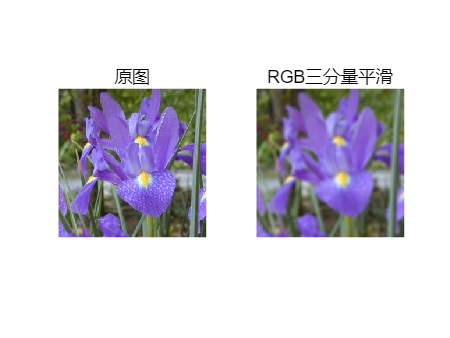

h_filter = fspecial('average', 7); % 7×7均值滤波器

% 对每个通道滤波
R_smooth = imfilter(img_rgb(:,:,1), h_filter, 'replicate');
G_smooth = imfilter(img_rgb(:,:,2), h_filter, 'replicate');
B_smooth = imfilter(img_rgb(:,:,3), h_filter, 'replicate');
img_smooth_all = cat(3, R_smooth, G_smooth, B_smooth);

% 显示结果
figure;
subplot(1,2,1), imshow(img_rgb), title('原图');
subplot(1,2,2), imshow(img_smooth_all), title('RGB三分量平滑');